# OpenTrafficLab: Simulating simple traffic scenarios with provided human driving models, or user defined models

This example shows how to use the OpenTrafficLab environment in MATLAB® to simulate simple traffic scenarios. By the the end of this document you will have seen:

- How to create a drivingScenario object and link it with OpenTrafficLab in order to generate traffic simulation.

- How to assign junction controllers to intersections and their turns and movements.

- How to create vehicles and choose a driving logic for them, as well generate their entry times by specifying injection rates at entry nodes.

- How to simulate and visualize the created scenario

- How to create your own vehicle and junction controllers to simulate the performance of your own algorithms.

We will use several helper functions contained in the Testing folder of the repository, so we first add it to the path:


% Add that folder plus all subfolders to the path.
addpath(genpath(pwd));

## Introduction

OpenTrafficLab builds upon the structure of the Driving Scenario Designer App, and its drivingScenario object by adding three main classes used for simulaiton.

- A Node class that is used to represent the road network as a directed graph where each node correspond to a lane within a road segment or turn/maneuver at an intersection. The edges of the graph indicate how cars can go from one node to the next, which in turn encodes the allowed traffic flow directions and turns.

- A DrivingStrategy class that serves as a vehicle controller. To implement a desired control logic, users can create a child class to DrivingStrategy and override the main methods where the driving logic is instantiated. The nominal logic implements standard car following models, namely the Gipps model or the Intelligent Driver Model (IDM) suitably modified to respong to upcoming traffic controllers (traffic lights etc...)

- A TrafficController (JunctionStrategy) class that allows users to model traffic signalization and control like traffic lights, stop signs or any user defined logic. The TrafficController is an Actor in the simulation that actts on a group of Nodes, say all turns/maneuvers at a junction, and controls wether each one is open or closed at any given time. A closed Node will a act as a stationary vehicle for incoming traffic, which will make the vehicles stop at the exit of the previous lane. Users can inherit from TrafficController to implement their own control logic. We provide one such inherited class: TrafficLight, which implements the logic of a traffic light controller.

Simulations can be run by creating the road network and its associated nodes, populating the scenario with actors and their control strategies (i.e DrivingStrategy and TrafficController), and then calling the advance function like in other drivingScenario simulations.

## Creating drivingScenario object and connecting it to OpenTrafficLab

### Drawing the roads

The simulator builds heavily on the Driving Scenario Designer and its different classes. The first step in running a simulation is to create a drivingScenario object containing the road segments of the network. Each turn or maneuver at a junction must be defined as its own road segment. Two different functions are provided for generating the drivingScenario object, one for a T-junction, and one for a 4-way intersection. In this example, we will use the T-Junction scenario. The createTJunctionScenario creates programatically 3 two lane roads that feed an intersection, and it creates 6 road segments at the intersection, one for each possible turn cars can make.

scenario = createTJunctionScenario();

We can set the simulation's final time and time step, in seconds, here:

scenario.SampleTime = 0.1;
scenario.StopTime = 100;

We can plot the scenario using plot.

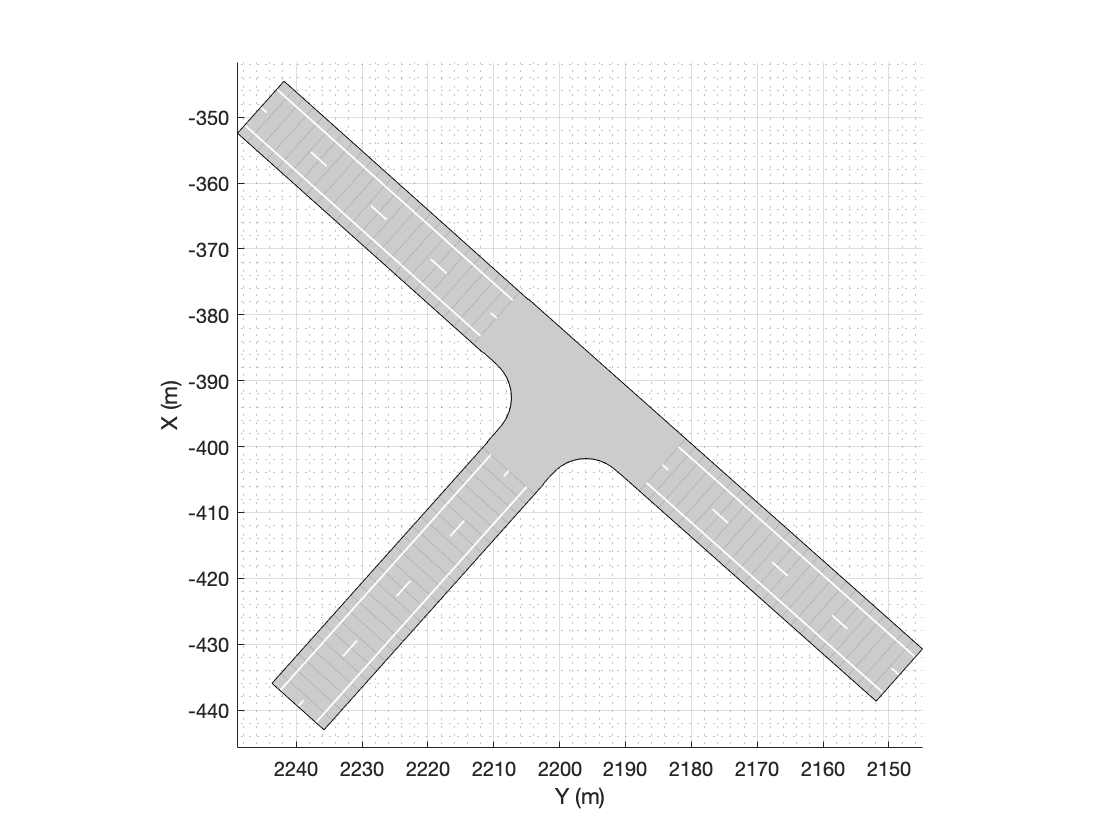

plot(scenario)

#### Note

Road segments for use in OpenTrafficLab need to be created carefully. In the Driving Scenario Designer App, roads that overlap ceate common road tiles for both roads and lane markings are not shown; however, no new road segments that represent the possible turns in the intersection are created. For the purposes of traffic simulation using OpenTrafficLab, you will usually need to create road segments for every possible turn at an intersection.

### Create the OpenTrafficLab graph representation of the network

The simulator represents the network in a graph of Node objects (See Node class documentation). The Node object is associated with a single lane of a single road segment. Upon creation, the Node object generates a mapping between global position and station coordinate (i.e. the distance travelled along the length of the lane). We can create the Node objects and specify their connectivity for the above graph using the corresponding helper function, which takes as input the scenario we just created. See help Node, and the comments on the [helper function](matlab:open('./Testing\createTJunctionNetwork.m')) for details on how to  assign each lane to a new Node.

network = createTJunctionNetwork(scenario);

There are three lanes feeding the intersection, three lanes leaving it, and 6 possible maneuvers at the intersection. There are therefore 12 Nodes in the network we just created.

length(network)

ans = 12

Each of these Nodes has different properties used by the simulator and its vehicles and traffic controllers. ConnectsTo, ConnectsFrom, and SharesRoadWith are links to other Node objects that define the connectivity of the network. The Scenario, RoadSegment and Lane property are set upon initialization and connect the Node object to the underlying drivingScenario object. The Length and Mapping properties define the mapping between the station distance along the length of the lane and the global position; the Mapping property also contains information about the direction/curvature of the lane at each station distance. The Vehicles property stores a handle to vehicles currently travelling down the Node, and the TrafficController property points to the agent controlling the traffic at node, which is done by either allowing or not allowing vehicles to enter.

network(1)

ans =   Node with properties:

           ConnectsTo: [1×2 Node]
         ConnectsFrom: [0×0 Node]
       SharesRoadWith: [1×1 Node]
             Scenario: [1×1 drivingScenario]
          RoadSegment: [1×1 driving.scenario.RoadSegment]
                 Lane: -1
               Length: 50
              Mapping: [501×6 double]
             Vehicles: [0×0 driving.scenario.Vehicle]
           PlotHandle: []
    TrafficController: []


We can use the plotPath method of the Node class to show the nominal trajectory a vehicle would follow within each node. For example, Nodes 7 through 12 correspond to all the maneuvers at the intersection, let's visualize those trajectories.

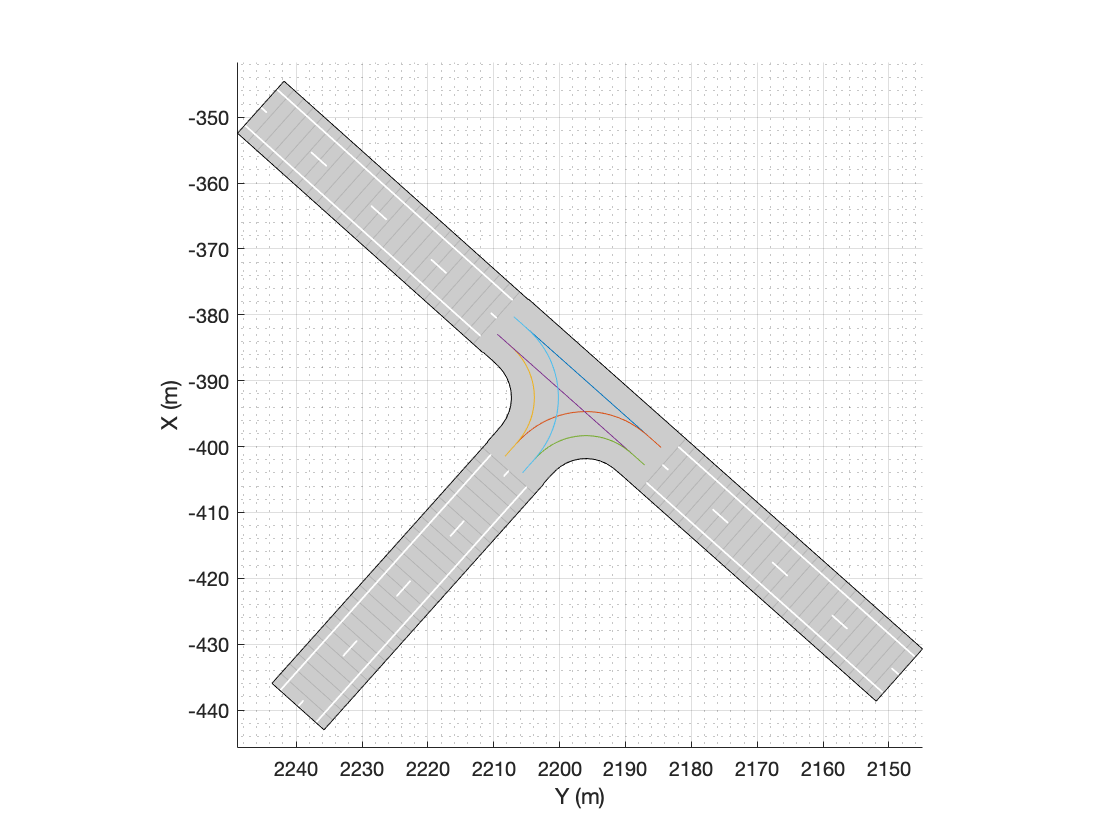

plot(scenario)
plotPath(network(7:12));

You can use the `ConnectsTo` property to navigate the networ of Nodes. For example, let's plot the paths of the first entry Node, and the two Nodes it connects to at the intersection.

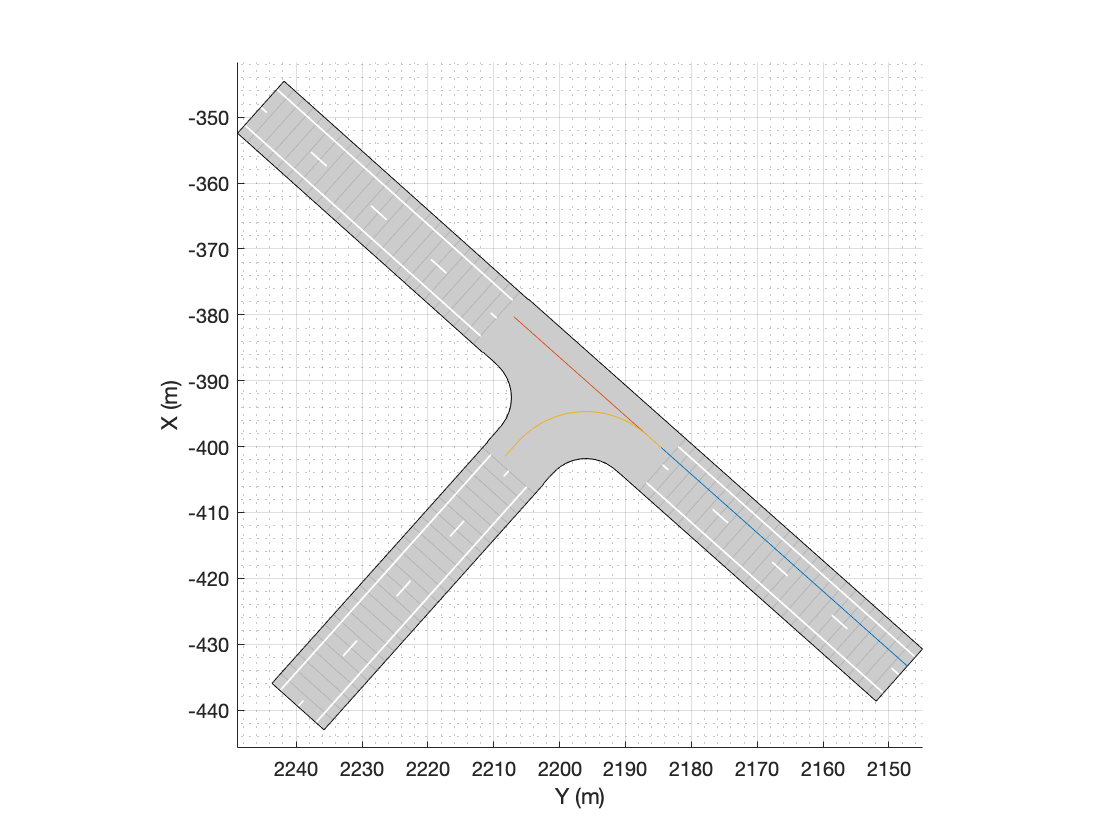

plot(scenario)
plotPath([network(1) network(1).ConnectsTo]);

## Creating a junction controller

Now that we have created a road network and its  OpenTrafficLab graph representation, we can create a controller for the intersection using the TrafficController class. Specifically, we will create a TrafficLight object which inherits from the TrafficController class. 

When created, all TrafficController objects need a single input:

- A vector of Node objects which the traffic controller operates on. Traffic is controlled by setting Nodes to be either open or closed to incoming traffic. Wehn a vehicle's upcoming Node is closed, the vehicle should stop.

The TrafficLight object in particular also needs two other inputs:

- The first is a list of indeces that indicate to which clique (or phase group) each Node belongs to; this input is a vector which assigns each node to its clique. 

- The second input is a vector indicating the timing, in seconds, of the switches from one phase to the next. Each entry in this vector indicates when the light switches from servicing one clique to the next, in the order in which they are defined by the previous input.

% Rebuild scenario and network to clear plots
scenario = createTJunctionScenario;
network = createTJunctionNetwork(scenario);
scenario.SampleTime = 0.1;
scenario.StopTime = 100;
%Identify which Nodes in the network belong to the junction that will be controlled
nodesInJunction = network(7:end);
% Assign each Node to a its corresponding clique (i.e. signal phase)
cliques = [1,1,2,2,3,3];
% Create the fixed time cycle of the light
cycle = [0,15,30,45];
% Create the traffic light actor
trafficLight = trafficControl.TrafficLight(nodesInJunction,'Cliques',cliques,'Cycle',cycle);

## Creating vehicles, their drivers and their entry times

The main actors in the simulation are the vehicles. In OpenTrafficLab, as in Driver Scenario Designer, vehicles are Vehicle objects, and they are controlled by a MotionStrategy object. In a Driving Scenario Designer scene, the motion strategy is normally a predetermined space-time trajectory, created using the trajectory function. In OpenTrafficLab, the motion strategy is a DrivingStrategy object (see DrivingStrategy documentation), which allows closed loop simulation.

To create vehicles then, we must create two objects and link them together:

- First, we create a Vehicle object, using the function [vehicle](https://www.mathworks.com/help/driving/ref/drivingscenario.vehicle.html?s_tid=srchtitle). The key input for this construction is the vehicle's entry time. 

- Second, we create a DrivingStrategy object (or a child class of it). The main and only required input for the DrivingStrategy is the vehicle's path through the network. This is given by a list Nodes in the order which the vehicle will traverse the network, including its first Node.

To facilitate the modelling of the arrival time, the simulator includes a function that generates arrival instances according to a Poisson arrival proocess. See [drivingBehavior.generatePoissonEntryTimes](matlab:open('./+drivingBehavior\generatePoissonEntryTimes.m')).

For this example we will use the [createVehiclesForTJunction](matlab:open('./Testing\createVehiclesForTJunction.m')) helper function to create the vehicles and their drivers. This helper function takes as input:

- The drivingScenario object

- The list of Nodes in the network

- The injection or arrival rate in vehicles per hour at each entry Node of the network (i.e .Nodes 1, 2, and 3 of the array `network`). This is given as a 3-by-1 vector of arrival rates.

- The turn ratio for vehicles at the intersection. This is a 2-by-1 vector (or 3-by-1 if using the four-way-intersection scenario) indicating what ratio of vehicles turn into the first or second Node that their entry Node connects to. That is, for vehicles entering in `network(1)`, a turn ratio of `[40, 60]` will create paths for vehicles so that 40% of vehicles procede into `network(1).ConnectsTo(1)`, and 60% proceed to` network(1).ConnectsTo(2)`

- *Optional*`: `A function handle to the DrivingStrategy constructor to be used. The default uses the standard DrivingStratgy construct, which would create the nominal DrivingStrategy object. See [DrivingStrategy](matlab:open('./@DrivingStrategy\DrivingStrategy.m')) for details on how the nominal driving strategy works. To create user defined drivers, create a function handle using the constructor of a user defined class which inherits from DrivingStrategy.

InjectionRate = [700, 700, 700]; % veh/hour
TurnRatio = [40, 60];
fnc = @(varargin) DrivingStrategy(varargin{:},'CarFollowingModel','Gipps');
cars = createVehiclesForTJunction(scenario,network,InjectionRate, TurnRatio,fnc);

## Simulating traffic

Traffic is now ready to be simulated. To run a simulation we call the `advance` function on the drivingScenario object. We can use the `plotOpenPaths` of the `TrafficLight` class to show the state of the traffic light at the intersection

Invalid or deleted object.

Error in trafficControl.TrafficController/plotOpenPaths (line 72)
                p.XData = node.Mapping(:,2);

% Make figure a pop-up, for animation purposes
figure('visible','on')
ax = gca;

% Plot the Scenario
plot(scenario,'Parent',ax)

%Advance the Scenario
 while advance(scenario)  
     plotOpenPaths(trafficLight)
    drawnow limitrate
 end